%%FigF: Eigenvalue convergence, Spatial POD
clear all;
load('Y:\rawdata\Sandia_cavity\StructuresToPlot_AIAAJournal\FigF.mat');
eig1 = load(FigF.completeName);
FigF

FigF = struct with fields:
           lname: 'Eigenvalue convergence SPOD'
    completeName: 'Y:\rawdata\Sandia_cavity\ConvergenceResults\Mach0.8\eigval_ensN_5000.txt'
             pts: [1×100 double]
          xtick1: [20 40 60 80 100]
          ytick1: [0 0.2000 0.4000 0.6000 0.8000 1]
         xlabel1: 'l'
         ylabel1: '\eta_c_o_n_v'
            mpts: [1 10 20 30 40 50 60 70 80 90 100]
           ylim1: [0 1]


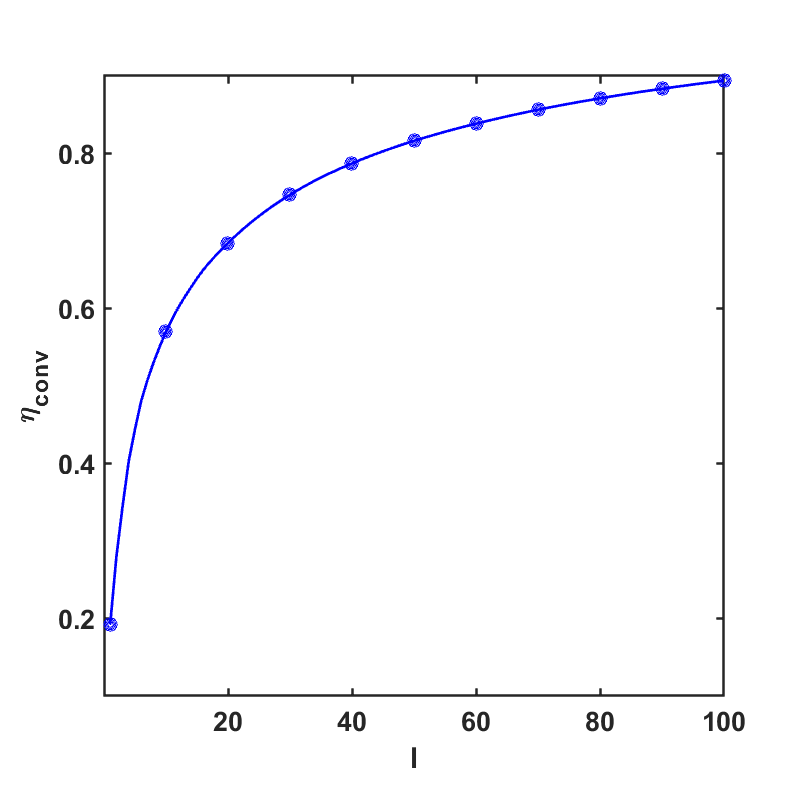

eig2 = en_cnvr_ary(eig1);
plot(FigF.pts,eig2(FigF.pts),'Color',[0 0 1],'LineWidth',2);
hold on;
plot(FigF.mpts,eig2(FigF.mpts),'o','MarkerEdgeColor',[0 0 1],'MarkerSize',8);

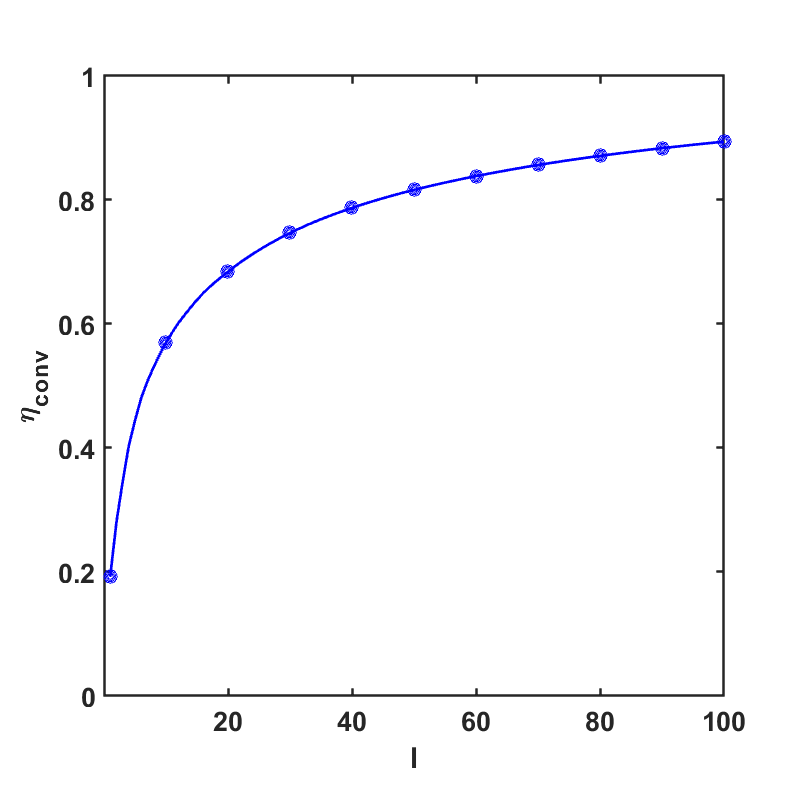

format_graph(1);
xticks(FigF.xtick1);
yticks(FigF.ytick1);
xlabel(FigF.xlabel1);
ylabel(FigF.ylabel1);
ylim(FigF.ylim1);

%%FigG
clear all;
load('Y:\rawdata\Sandia_cavity\StructuresToPlot_AIAAJournal\FigG.mat');
eig1 = load(FigG.completeName);
FigG

FigG = struct with fields:
           lname: 'FPOD lambda vs f'
    completeName: 'Y:\rawdata\Sandia_cavity\SpectralConvergenceResults\eigval_280.txt'
             pts: [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46]
           xlim1: [0.0441 2]
           ylim1: [0 0.0500]
         xlabel1: 'St_L'
         ylabel1: '\eta_l_,_f'
            xpts: [1×45 double]
          xtick1: [0.5000 1 1.5000 2]
          ytick1: [1×41 double]
         legend1: {'l=1'  'l=2'  'l=3'}
            ross: [4×1 double]


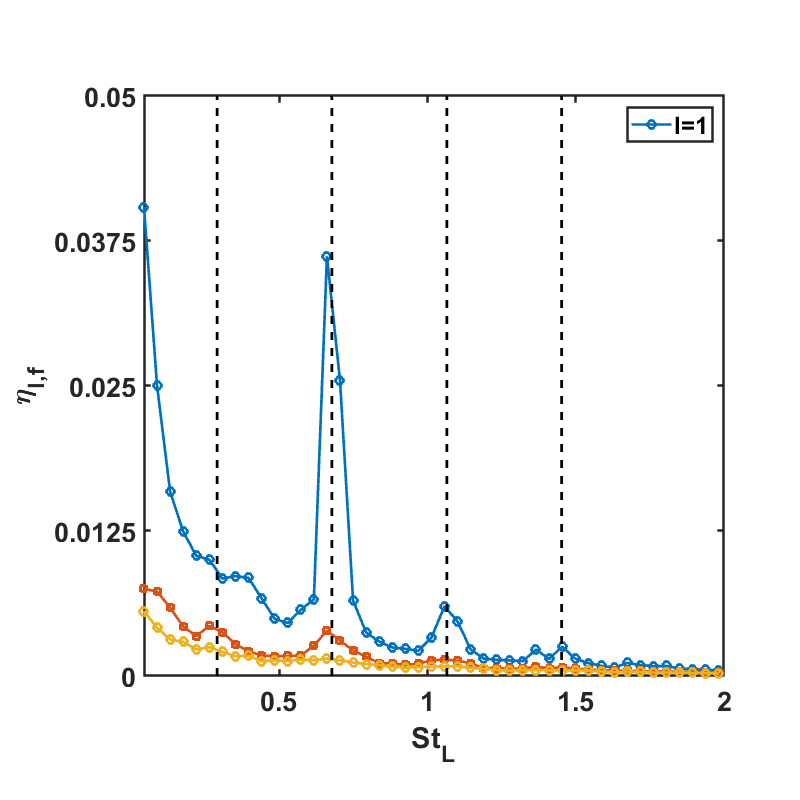

hold off;

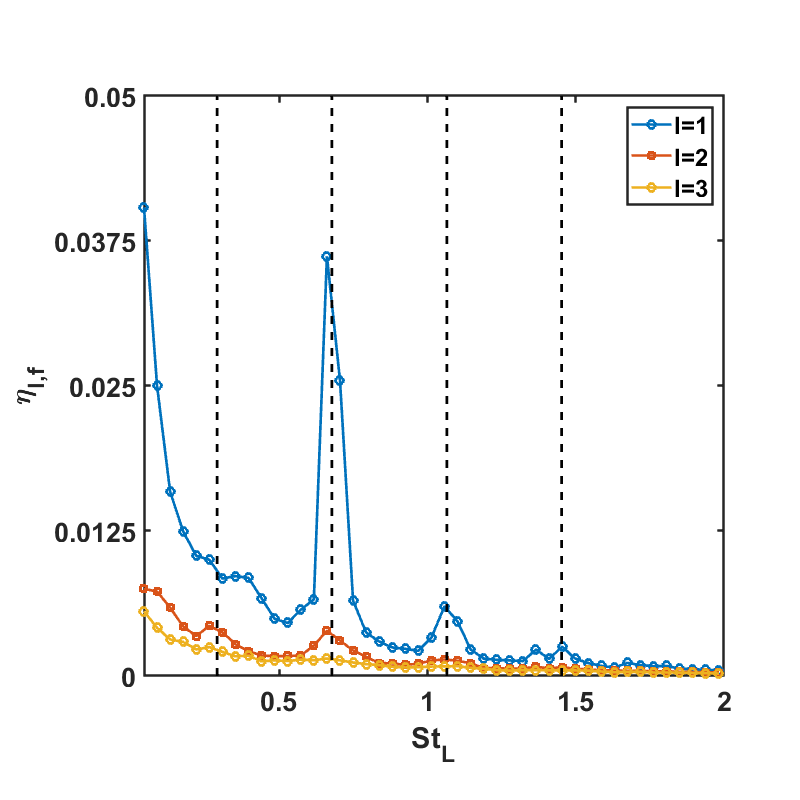

eig2 = eig1/sum(sum(eig1));
%plot(FigG.xpts,eig2(1,FigG.pts),'o-',FigG.xpts,eig2(2,FigG.pts),'s-',FigG.xpts,eig2(3,FigG.pts),'^-','LineWidth',2);
plot(FigG.xpts,eig2(1,FigG.pts),'o-','LineWidth',2);
hold on; 
plot(FigG.xpts,eig2(2,FigG.pts),'s-','LineWidth',2);
plot(FigG.xpts,eig2(3,FigG.pts),'o-','LineWidth',2);
format_graph(1);
xlim(FigG.xlim1), ylim(FigG.ylim1);
xticks(FigG.xtick1), yticks(FigG.ytick1);
for ros_ind = 1:4
    plot([FigG.ross(ros_ind) FigG.ross(ros_ind)],FigG.ylim1,'--','Color',[0 0 0],'LineWidth',2)
end
xlabel(FigG.xlabel1,'FontSize',34,'FontWeight','Bold'), ylabel(FigG.ylabel1,'FontSize',34,'FontWeight','Bold')
legend(FigG.legend1)

%% FigH
clear all;
load('Y:\rawdata\Sandia_cavity\StructuresToPlot_AIAAJournal\FigH.mat');
eig1 = load(FigH.completeName);
FigH

FigH = struct with fields:
           lname: 'FPOD lambda vs l'
    completeName: 'Y:\rawdata\Sandia_cavity\SpectralConvergenceResults\eigval_280.txt'
          findex: [6 16 25]
             pts: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50]
           xlim1: [1 50]
           ylim1: [0 1]
         xlabel1: 'l'
         ylabel1: '\eta_l_,_f'
         legend1: {'RF 1'  'RF 2'  'Rf 3'}
          xtick1: [10 20 30 40 50]
          ytick1: [0 0.2000 0.4000 0.6000 0.8000 1]
            mpts: [1 5 10 15 20 25 30 35 40 45 50]


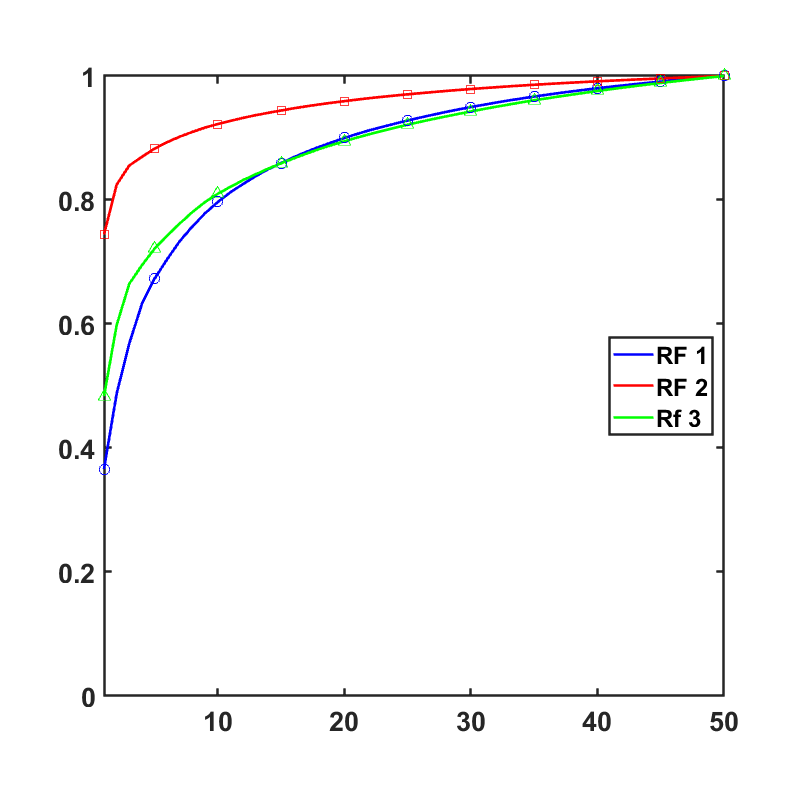

hold off;

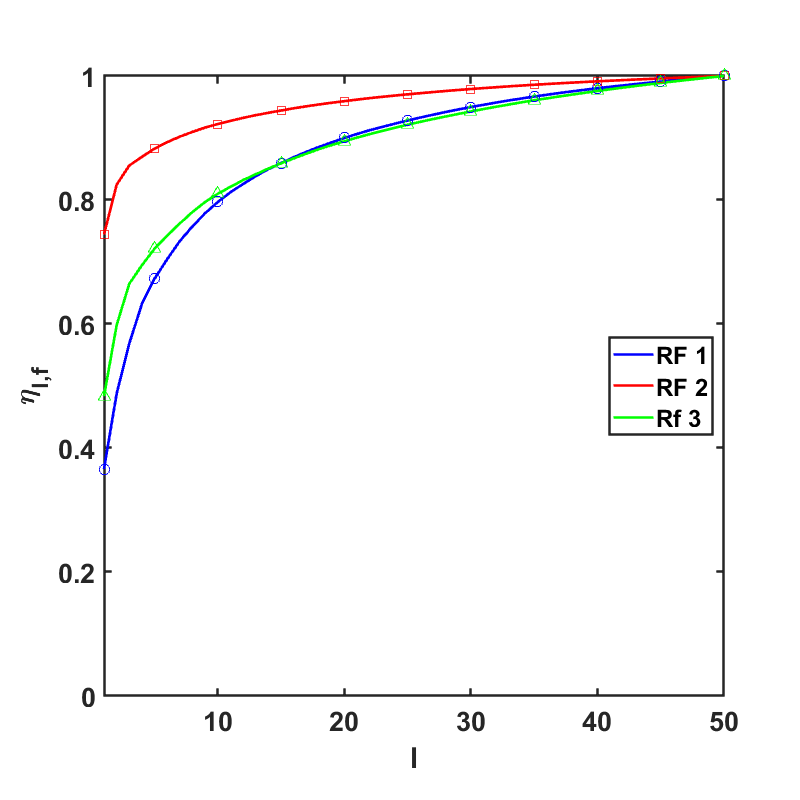

eig2 = eig1/sum(sum(eig1));
eig3 = en_cnvr_ary(eig2(FigH.pts,FigH.findex(1))/sum(eig2(FigH.pts,FigH.findex(1))));
plot(FigH.pts,eig3,'Color',[0 0 1],'LineWidth',2);
hold on;
eig4 = en_cnvr_ary(eig2(FigH.pts,FigH.findex(2))/sum(eig2(FigH.pts,FigH.findex(2))));
plot(FigH.pts,eig4,'Color',[1 0 0],'LineWidth',2);
eig5 = en_cnvr_ary(eig2(FigH.pts,FigH.findex(3))/sum(eig2(FigH.pts,FigH.findex(3))));
plot(FigH.pts,eig5,'Color',[0 1 0],'LineWidth',2);

plot(FigH.mpts,eig3(FigH.mpts),'o','MarkerEdgeColor',[0 0 1],'MarkerSize',8);
plot(FigH.mpts,eig4(FigH.mpts),'s','MarkerEdgeColor',[1 0 0],'MarkerSize',8);
plot(FigH.mpts,eig5(FigH.mpts),'^','MarkerEdgeColor',[0 1 0],'MarkerSize',8);
xlim(FigH.xlim1), ylim(FigH.ylim1);
format_graph(1);
xticks(FigH.xtick1), yticks(FigH.ytick1);
legend(FigH.legend1,'Location','East');
xlabel(FigH.xlabel1,'FontSize',34,'FontWeight','Bold'), ylabel(FigH.ylabel1,'FontSize',34,'FontWeight','Bold')

%% FigK
clear all;
load('Y:\rawdata\Sandia_cavity\StructuresToPlot_AIAAJournal\FigK.mat');
FigK

FigK = struct with fields:
            lname: 'Rms SPOD energy levels'
    completeName1: 'Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\35PercentEnergy_3\uv_rec_var.txt'
    completeName2: 'Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\50PercentEnergy_7\uv_rec_var.txt'
    completeName3: 'Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\75PercentEnergy_31\uv_rec_var.txt'


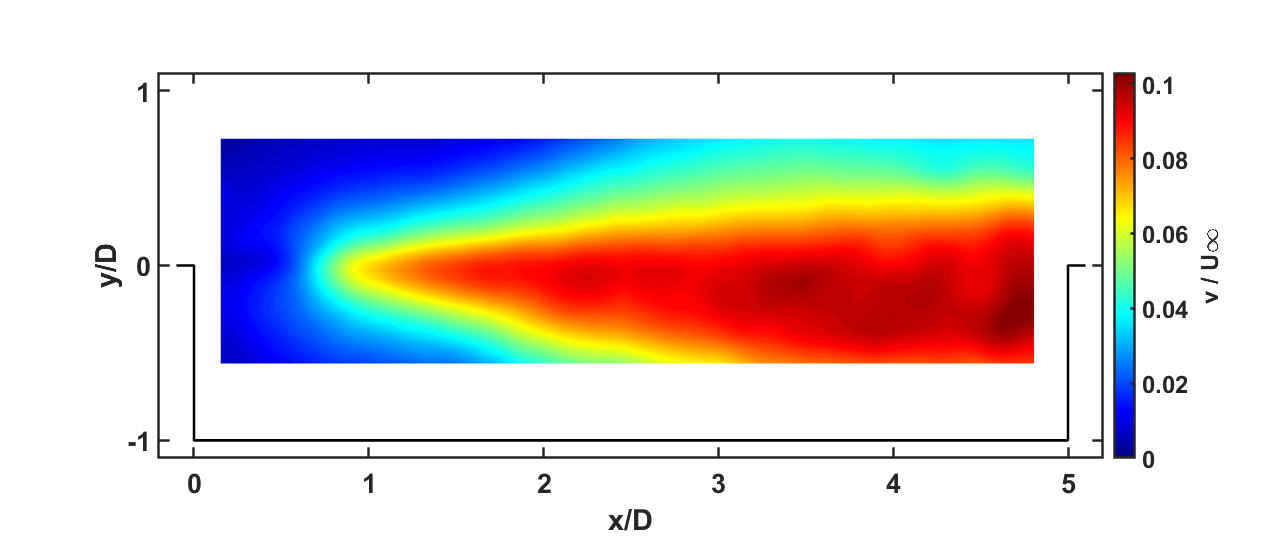

hold off;

[L,D,Mach,Uinf,Fs,N,Nb] = load_parameters(1);
uv1 = load(FigK.completeName1);
uv2 = load(FigK.completeName2);
uv3 = load(FigK.completeName3);

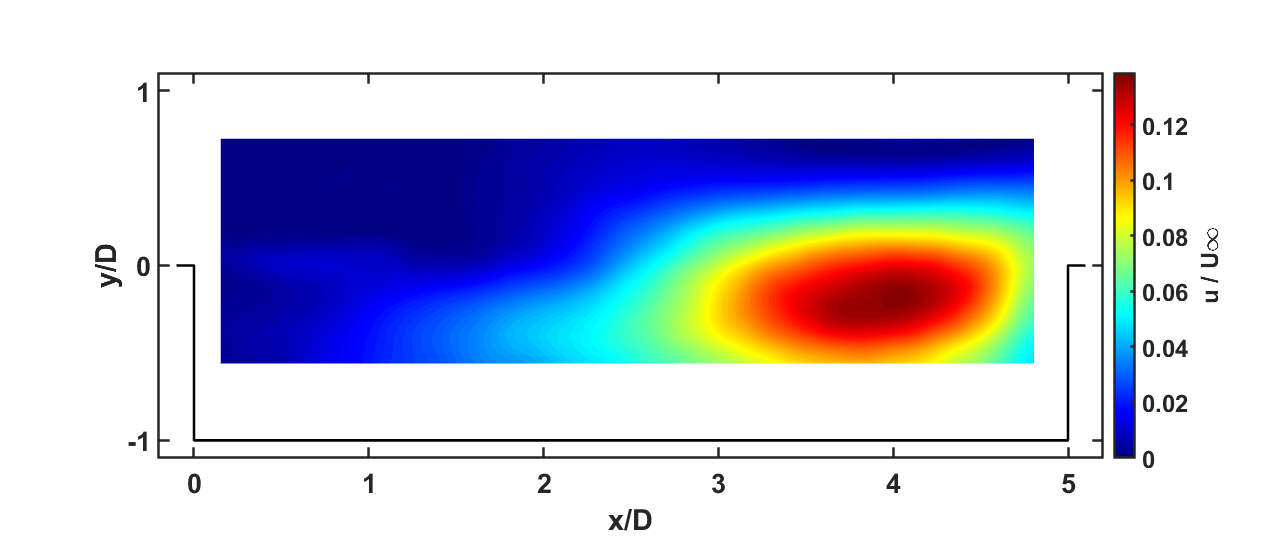

%FigK11
uv_rec = Var2Rms(uv1);
plot_cont_rms(uv_rec,1);

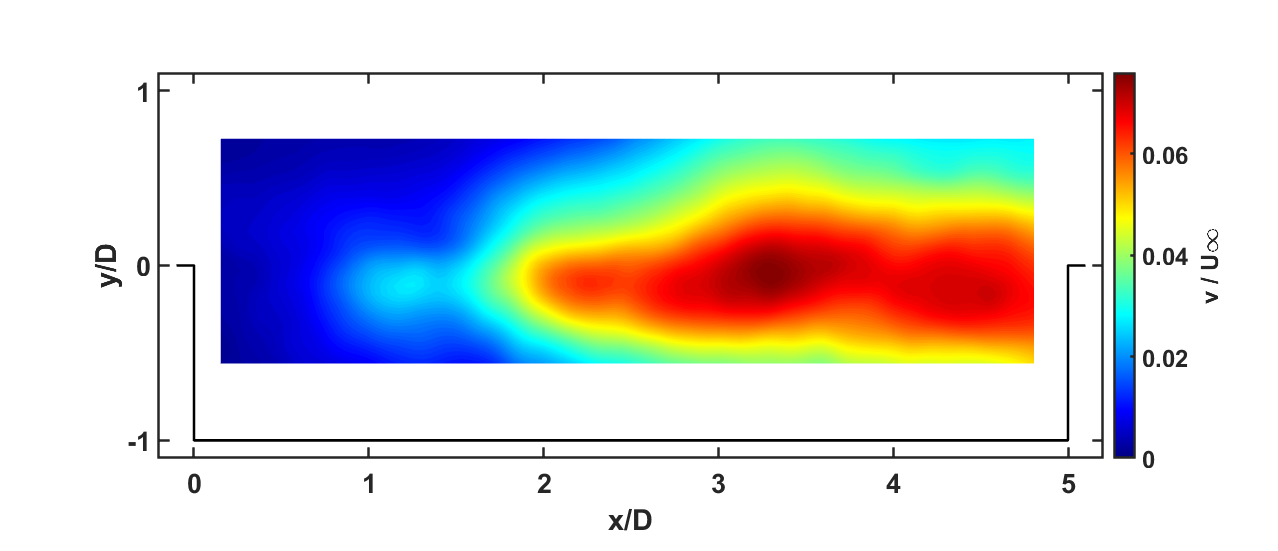


%FigK12
uv_rec = Var2Rms(uv1);
plot_cont_rms(uv_rec,2);

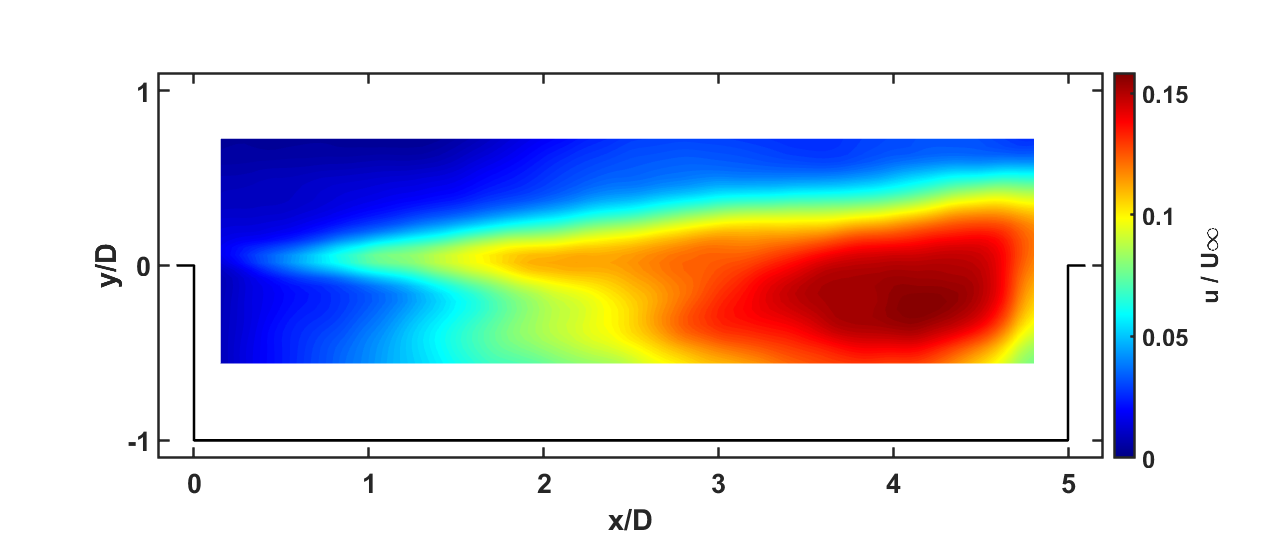

%FigK21
uv_rec = Var2Rms(uv2);
plot_cont_rms(uv_rec,1);

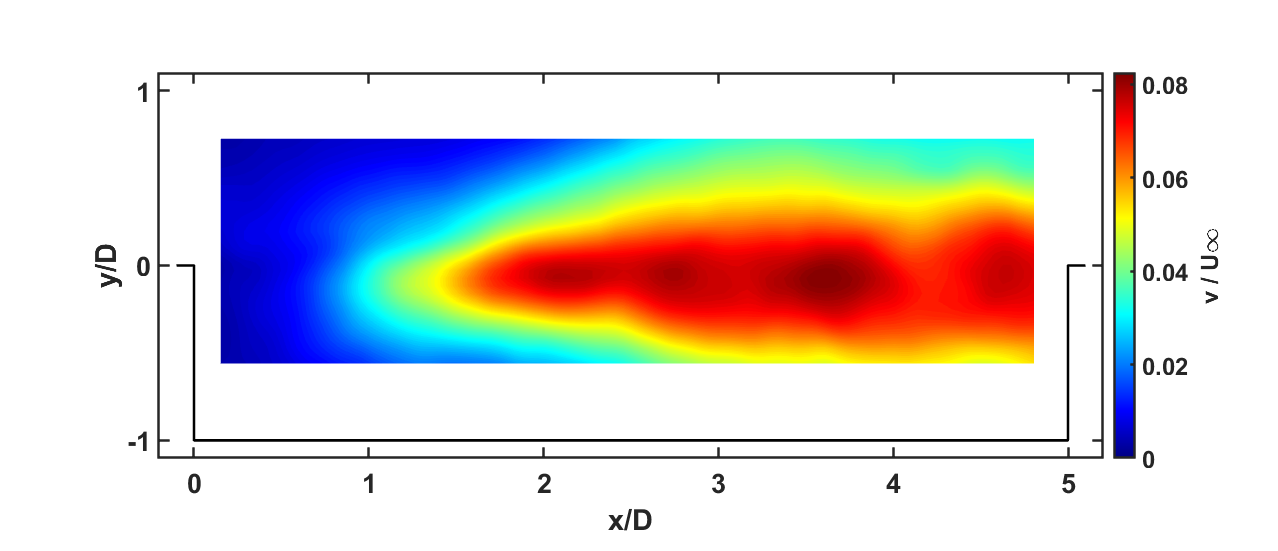

%FigK22
uv_rec = Var2Rms(uv2);
plot_cont_rms(uv_rec,2);

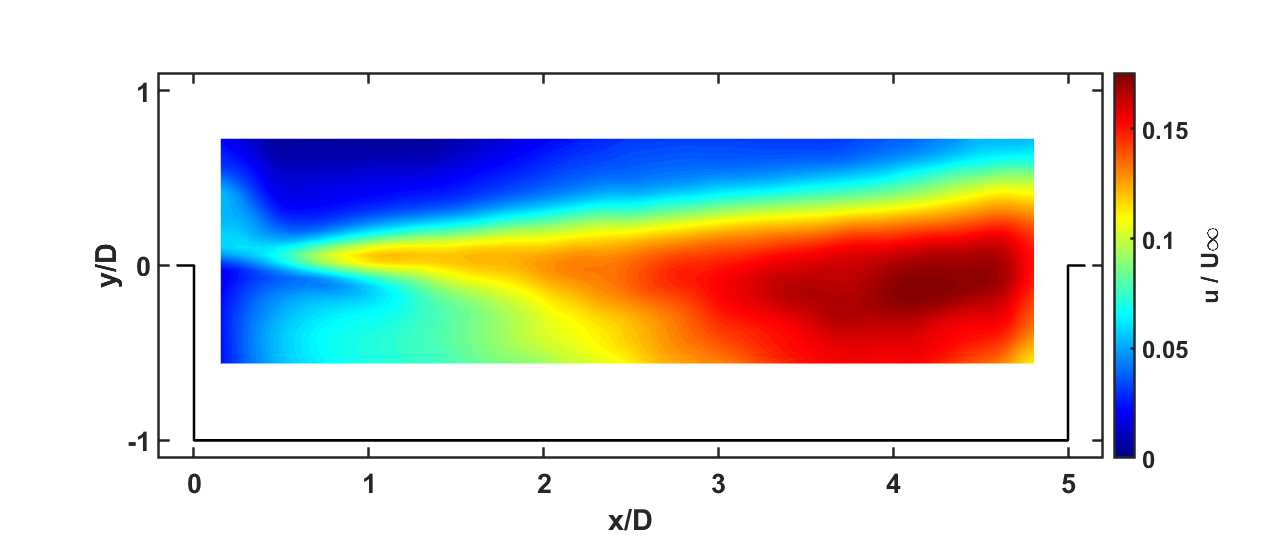

%FigK31
uv_rec = Var2Rms(uv3);
plot_cont_rms(uv_rec,1);

%FigK32
uv_rec = Var2Rms(uv3);
plot_cont_rms(uv_rec,2);

%%FigE
clear all;
load('Y:\rawdata\Sandia_cavity\StructuresToPlot_AIAAJournal\FigE.mat');
FigE

FigE = struct with fields:
           lname: 'Rms velocity measured'
    completeName: 'Y:\rawdata\Sandia_cavity\Spectral velocity data\vel_ens\Mach0.8\uv_rec_var.txt'


[L,D,Mach,Uinf,Fs,N,Nb] = load_parameters(1);
uv = load(FigE.completeName);

%FigE1
hold off;

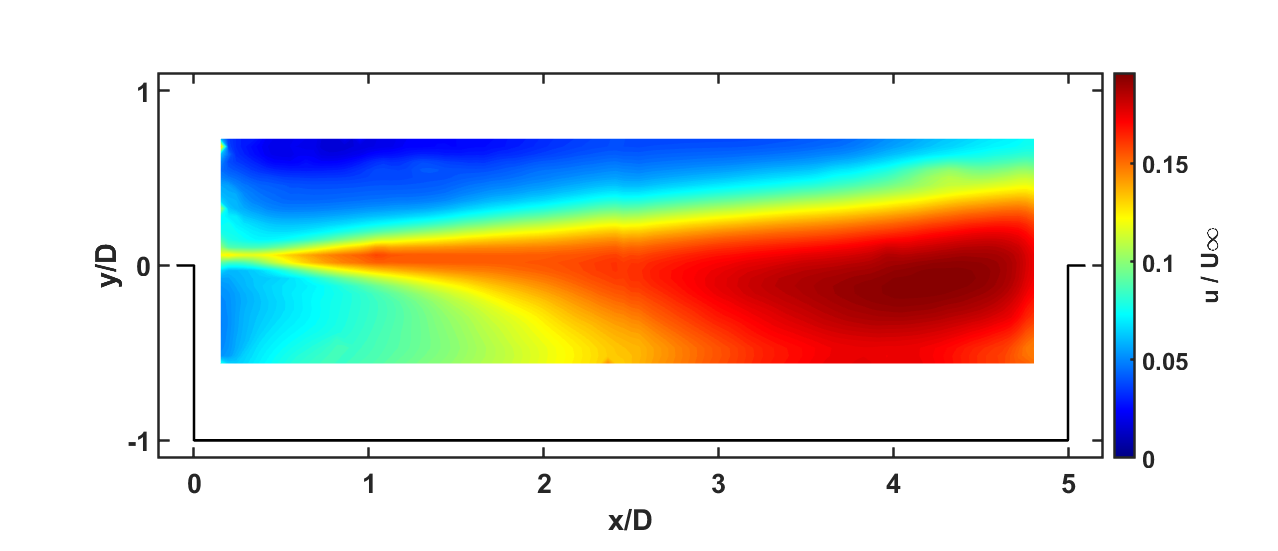

uv_rec = Var2Rms(uv);
plot_cont_rms(uv_rec,1);

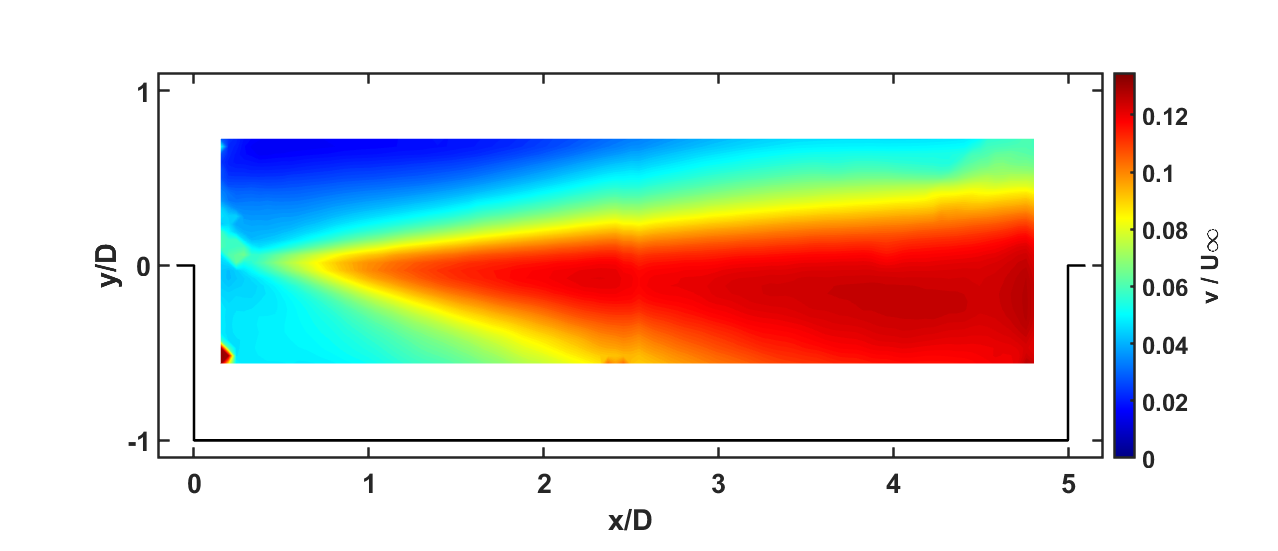

%FigE2
plot_cont_rms(uv_rec,2);

## FigL

clear all;
load('Y:\rawdata\Sandia_cavity\StructuresToPlot_AIAAJournal\FigL.mat');
FigL

FigL = struct with fields:
            lname: 'Rms FPOD energy levels'
    completeName1: 'Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\DecreasingEnergy\35Energy_37modes\uv_rec_var.txt'
    completeName2: 'Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\DecreasingEnergy\50Energy_146modes\uv_rec_var.txt'
    completeName3: 'Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\75PercentEnergy_31\uv_rec_var.txt'


uv1 = load(FigL.completeName1);
uv2 = load(FigL.completeName2);

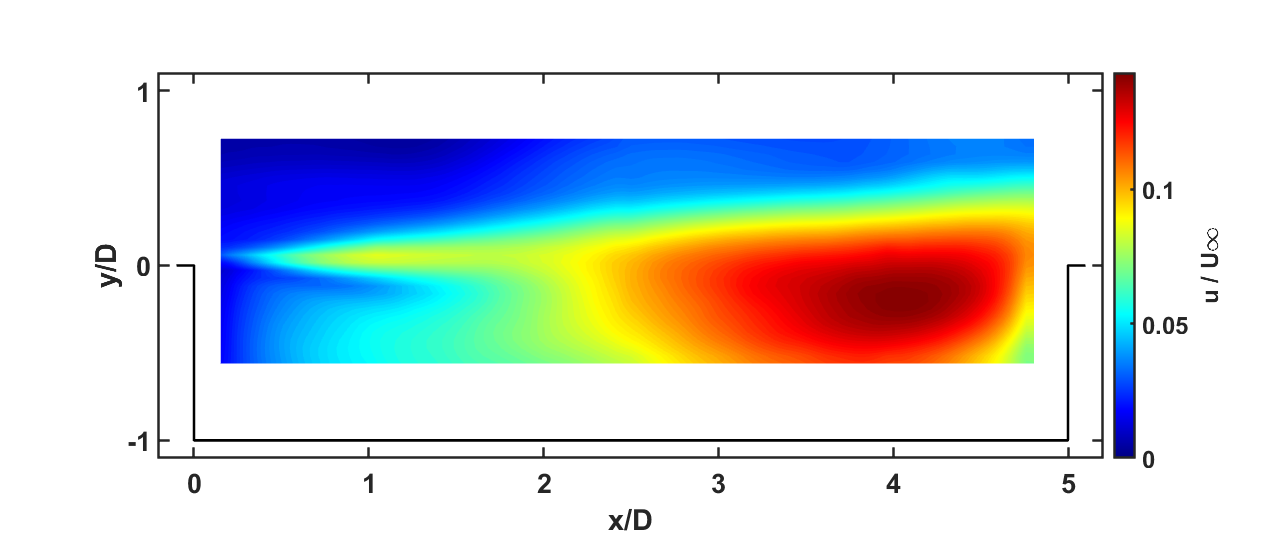

uv_rec = Var2Rms(uv1);
plot_cont_rms(uv_rec,1);

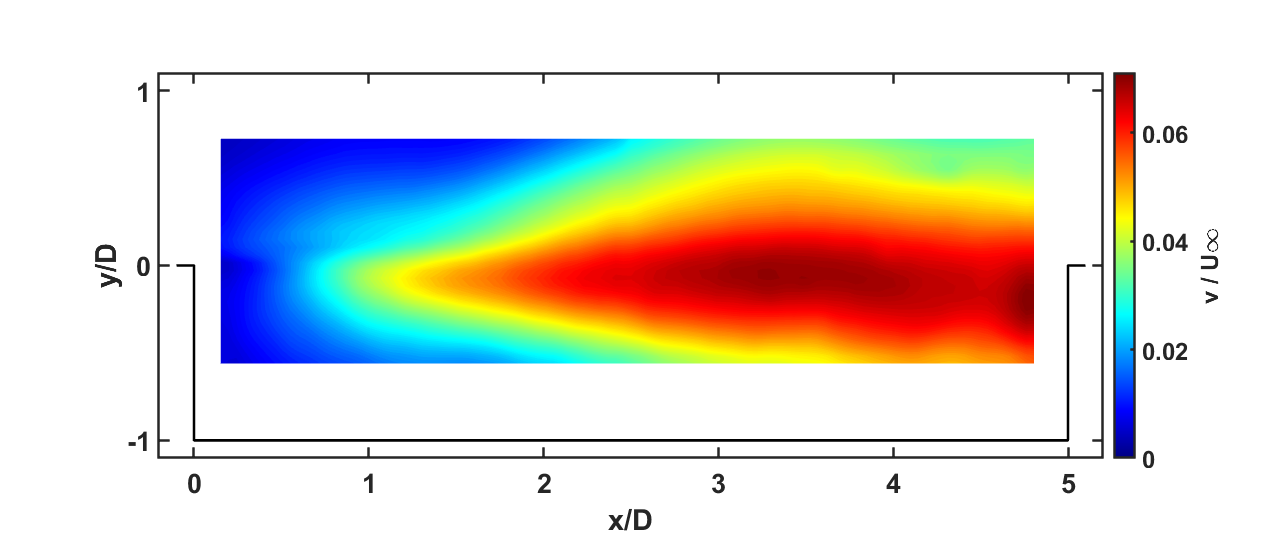

plot_cont_rms(uv_rec,2);

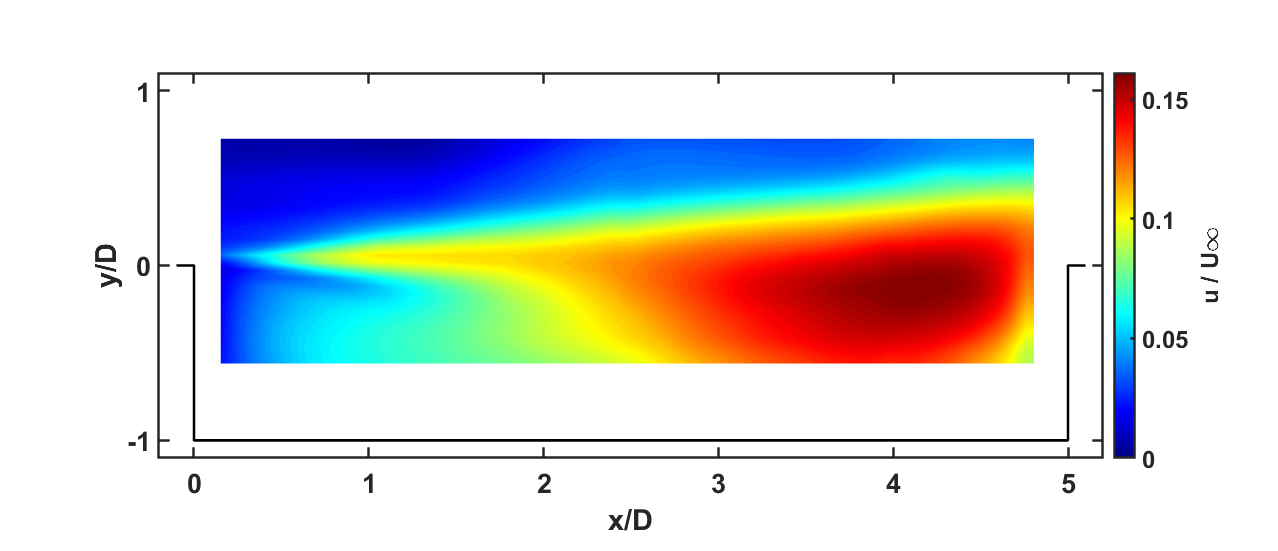

uv_rec = Var2Rms(uv2);
plot_cont_rms(uv_rec,1);

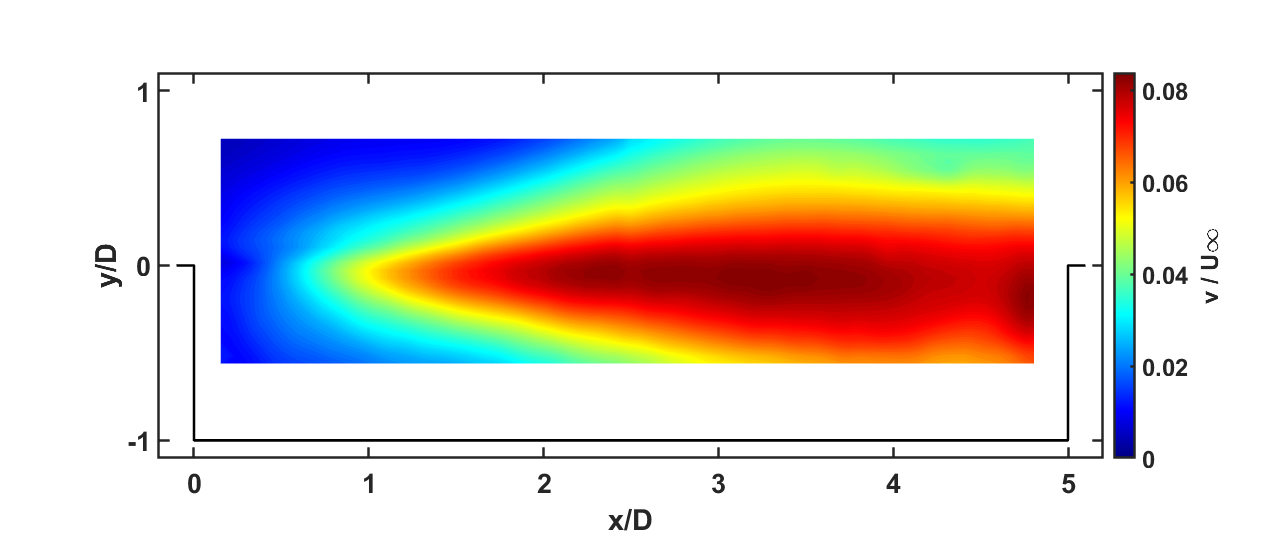

plot_cont_rms(uv_rec,2);

## FigI

clear all;
load('Y:\rawdata\Sandia_cavity\StructuresToPlot_AIAAJournal\FigI.mat');
FigI

FigI = struct with fields:
            lname: 'Spatial POD vs FPOD'
    completeName1: 'Y:\rawdata\Sandia_cavity\SpectralConvergenceResults\eigval_280.txt'
    completeName2: 'Y:\rawdata\Sandia_cavity\ConvergenceResults\eigval_lf_N5000.txt'
              pts: [1×150 double]
             mpts: [1 10 20 30 40 50 60 70 80 90 100 110 120 130 140 150]
           xtick1: [30 60 90 120 150]
           ytick1: [0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000]
            ylim1: [0 0.6000]
            xlim1: [1 150]
          legend1: {'FPOD'  'SPOD'}
          xlabel1: 'Modes (l,f)'
          ylabel1: '\eta'


eig1 = load(FigI.completeName1);
eig2 = load(FigI.completeName2);
eig2 = eig2';

[eigD1, m_ind1, f_ind1] = DecEn_eigval(eig1);
[eigD2, m_ind2, f_ind2] = DecEn_eigval(eig2);
eigDA = en_cnvr_ary(eigD1);
eigDB = en_cnvr_ary(eigD2);

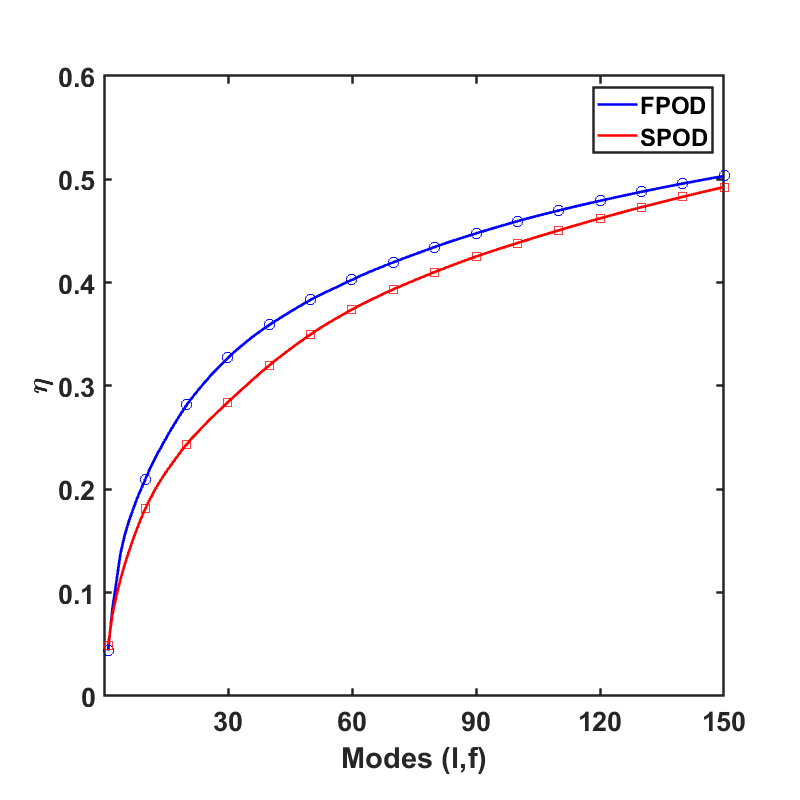

plot(FigI.pts, eigDA(FigI.pts),'Color',[0 0 1],'LineWidth',2);
hold on;
plot(FigI.pts, eigDB(FigI.pts),'Color',[1 0 0],'LineWidth',2);
plot(FigI.mpts,eigDA(FigI.mpts),'o', 'MarkerEdgeColor',[0 0 1], 'MarkerSize',8);
plot(FigI.mpts,eigDB(FigI.mpts), 's','MarkerEdgeColor',[1 0 0], 'MarkerSize',8);
legend(FigI.legend1)
format_graph(1);
hold off;
xticks(FigI.xtick1), yticks(FigI.ytick1)
xlabel(FigI.xlabel1,'FontSize',34,'FontWeight','Bold') 
ylabel(FigI.ylabel1,'FontSize',34,'FontWeight','Bold')

## FigM

clear all;
load('Y:\rawdata\Sandia_cavity\StructuresToPlot_AIAAJournal\FigM.mat');
FigM

FigM = struct with fields:
            lname: 'Rms FPOD Rossiter modes'
    completeName1: 'Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\RossiterModes\RossiterMode1\uv_rec_var.txt'
    completeName2: 'Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\RossiterModes\RossiterMode2\uv_rec_var.txt'
    completeName3: 'Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\RossiterModes\RossiterMode3\uv_rec_var.txt'


uv1 = load(FigM.completeName1);
uv2 = load(FigM.completeName2);
uv3 = load(FigM.completeName3);

uv3 =     0.2222    0.3470    0.1238    0.2885    0.0640    0.2088    0.0322    0.0582    0.0295    0.1947    0.2357    0.2235    0.1088    0.1156    0.0355    0.0220    0.1002    0.0568    0.2964    0.0729    0.0316    0.1251    0.1450    0.1656    0.3735    0.1219    0.1599    0.2192    0.2715    0.0652    0.6228    0.0875    0.2255    0.1302    0.0158    0.0368    0.3117    0.0271    0.1323    0.7544    0.0203    0.0804    0.0846    0.2001    0.2487    0.1271    0.2476    0.0950    0.0815    0.1443
    0.2437    0.3579    0.1269    0.2978    0.0684    0.2287    0.0460    0.0530    0.0402    0.2044    0.2331    0.2394    0.1088    0.1203    0.0453    0.0251    0.1056    0.0593    0.3014    0.0721    0.0339    0.1297    0.1529    0.1684    0.3982    0.1431    0.1772    0.2381    0.2855    0.0708    0.6574    0.0894    0.2273    0.1377    0.0169    0.0405    0.3334    0.0468    0.1384    0.7957    0.0206    0.0781    0.0843    0.1955    0.2703    0.1609    0.2554    0.0974    0.0792   

%Ross1 U
uv_rms = Var2Rms(uv1);
plot_cont_rms(uv_rec,1);

%Ross1 V
plot_cont_rms(uv_rec,2);

%Ross2 U
uv_rms = Var2Rms(uv2);
plot_cont_rms(uv_rec,1);

%Ross2 V
plot_cont_rms(uv_rec,2);

%Ross3 U
uv_rms = Var2Rms(uv3);
plot_cont_rms(uv_rec,1);

%Ross3 V
plot_cont_rms(uv_rec,2);

## FigN

clear all;
load('Y:\rawdata\Sandia_cavity\StructuresToPlot_AIAAJournal\FigN.mat');
FigN

FigN = struct with fields:
            lname: 'Rms Bandpass RF measured'
    completeName1: 'Y:\rawdata\Sandia_cavity\Spectral velocity data\vel_ens\RossiterMode1\uv_rec_var.txt'
    completeName2: 'Y:\rawdata\Sandia_cavity\Spectral velocity data\vel_ens\RossiterMode2\uv_rec_var.txt'
    completeName3: 'Y:\rawdata\Sandia_cavity\Spectral velocity data\vel_ens\RossiterMode3\uv_rec_var.txt'


uv1 = load(FigN.completeName1);
uv2 = load(FigN.completeName2);
uv3 = load(FigN.completeName3);

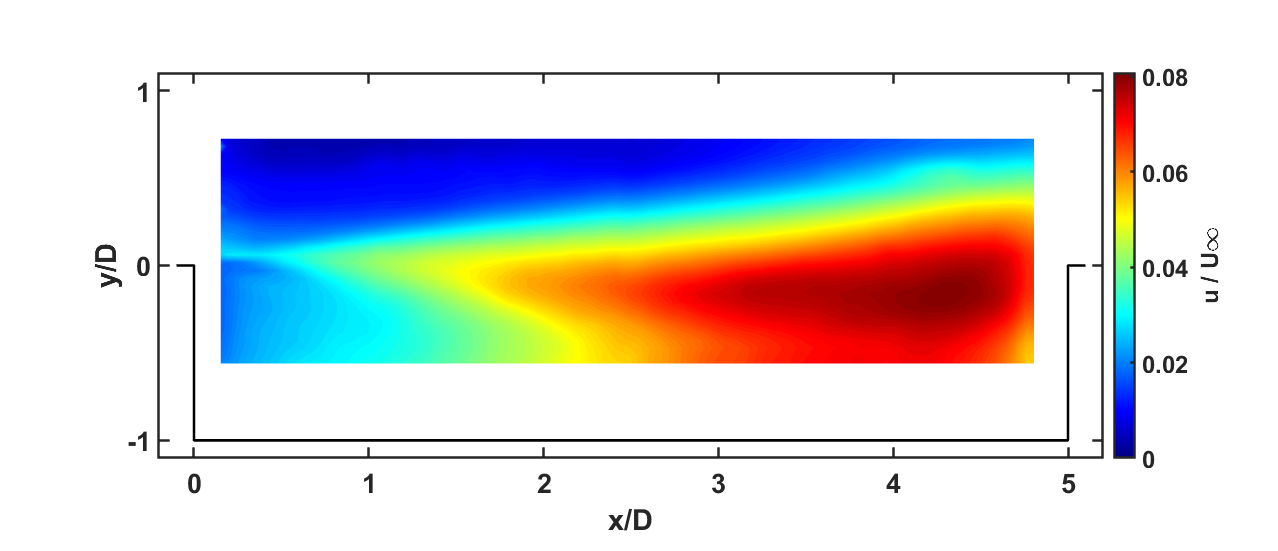

%Ross1 U
uv_rec = Var2Rms(uv1);
plot_cont_rms(uv_rec,1);

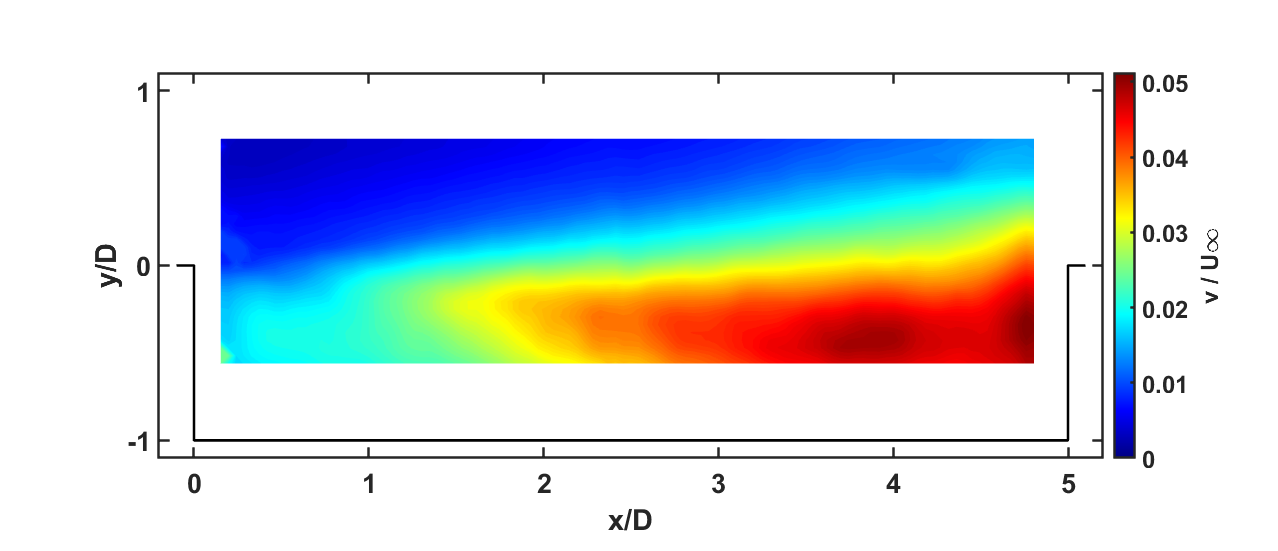

%Ross1 V
plot_cont_rms(uv_rec,2);

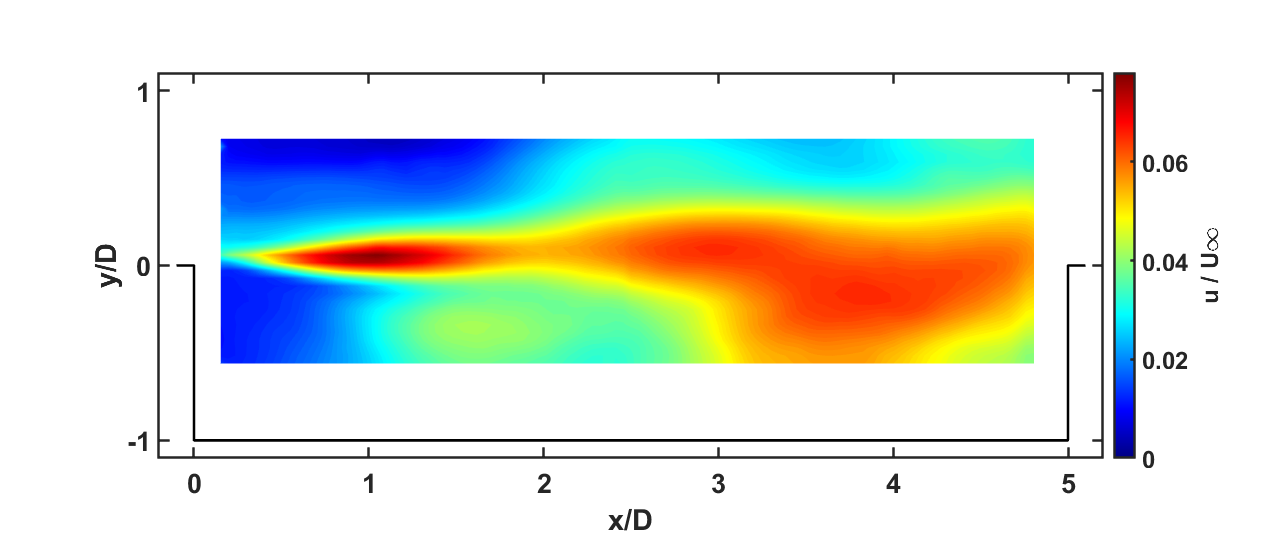

%Ross2 U
uv_rec = Var2Rms(uv2);
plot_cont_rms(uv_rec,1);

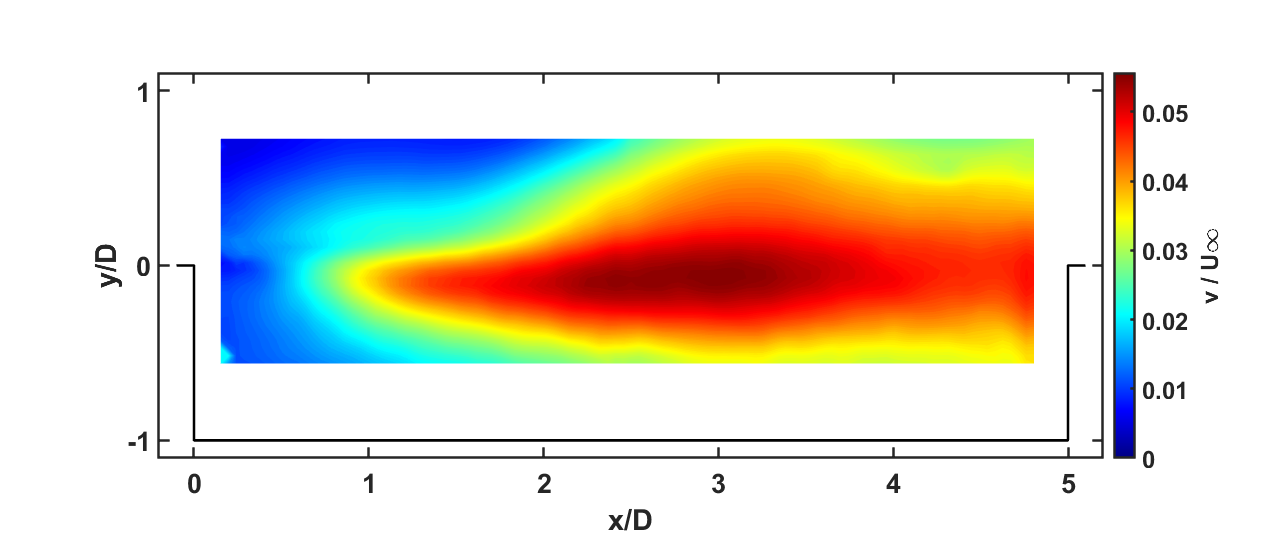

%Ross2 V
plot_cont_rms(uv_rec,2);

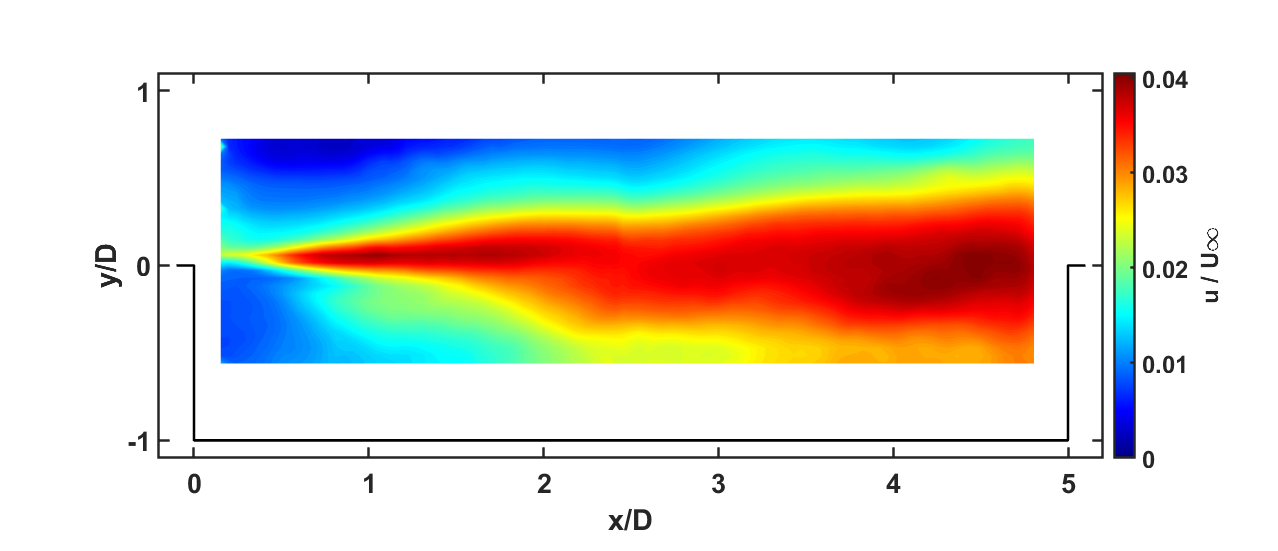

%Ross3 U
uv_rec = Var2Rms(uv3);
plot_cont_rms(uv_rec,1);

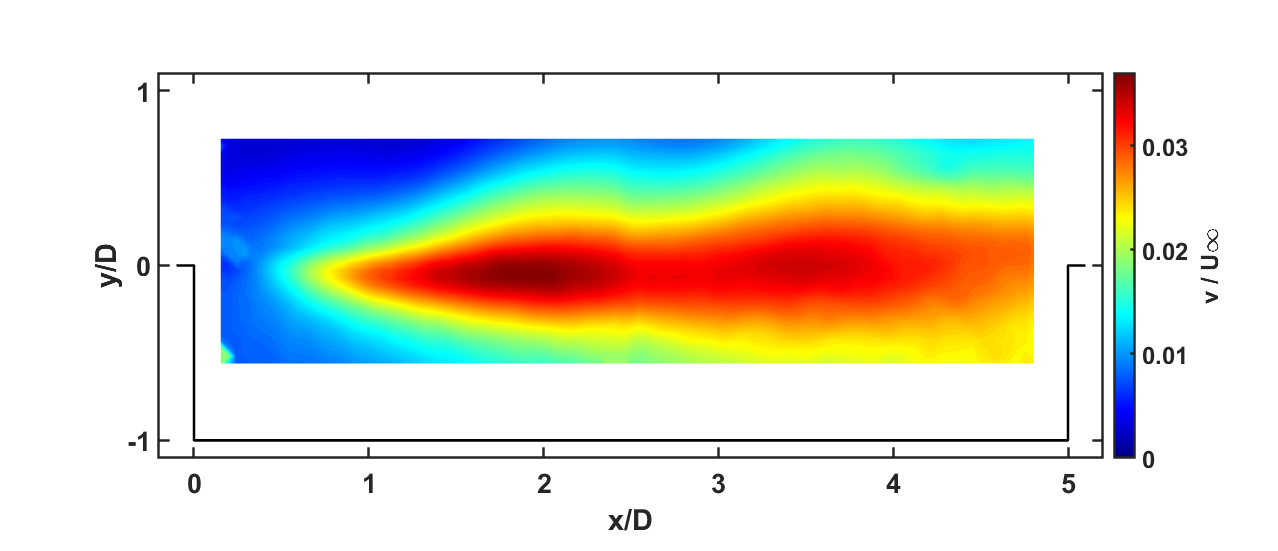

%Ross3 V
plot_cont_rms(uv_rec,2);

## FigO

clear all;
load('Y:\rawdata\Sandia_cavity\StructuresToPlot_AIAAJournal\FigO.mat');
FigO

FigO = struct with fields:
             lname: 'Rms Spatial POD Modewise'
     completeName1: 'Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\20PercentEnergy_1\uv_rec_var.txt'
     completeName2: 'Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\Mode2\uv_rec_var.txt'
     completeName3: 'Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\Mode3\uv_rec_var.txt'
     completeName7: 'Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\50PercentEnergy_7\uv_rec_var.txt'
    completeName16: 'Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\65PercentEnergy_16\uv_rec_var.txt'
    completeName31: 'Y:\rawdata\Sandia_cavity\SpatialVelocityReconstructions\75PercentEnergy_31\uv_rec_var.txt'


uv1 = load(FigO.completeName1);
uv2 = load(FigO.completeName2);
uv3 = load(FigO.completeName3);
uv16 = load(FigO.completeName16);

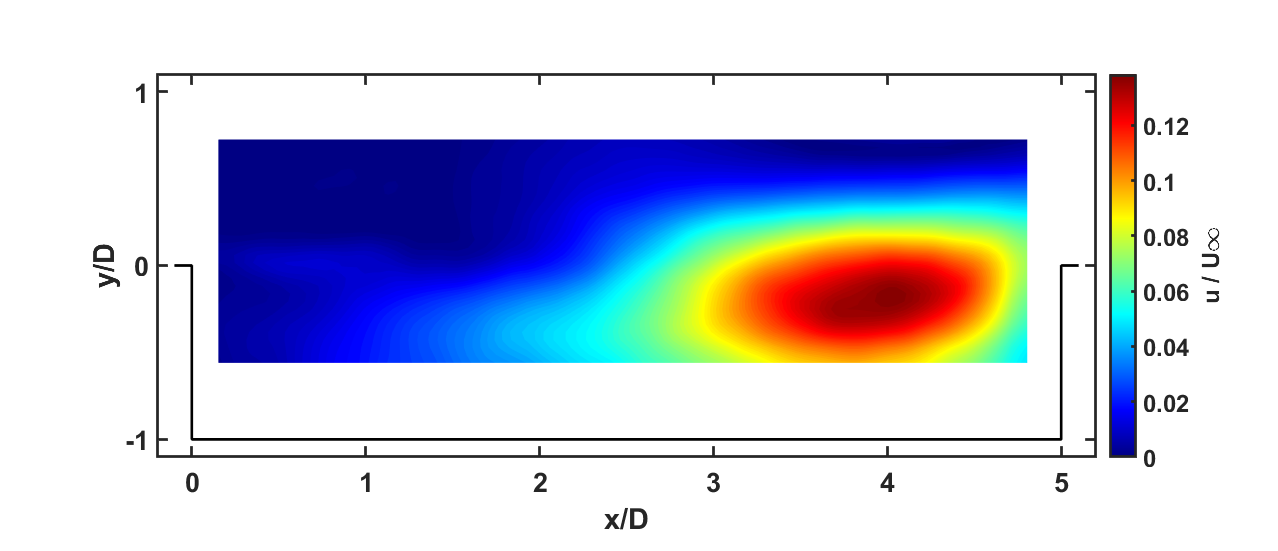

%%Mode1 U
uv_rec = Var2Rms(uv1);
plot_cont_rms(uv_rec,1);

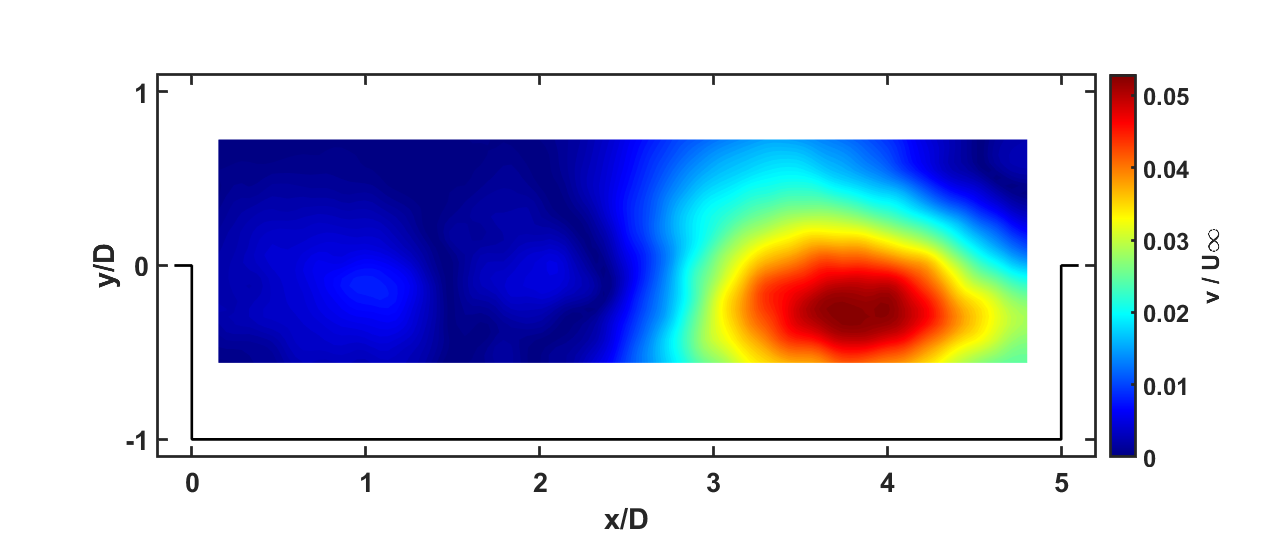

%%Mode1 V

plot_cont_rms(uv_rec,2);

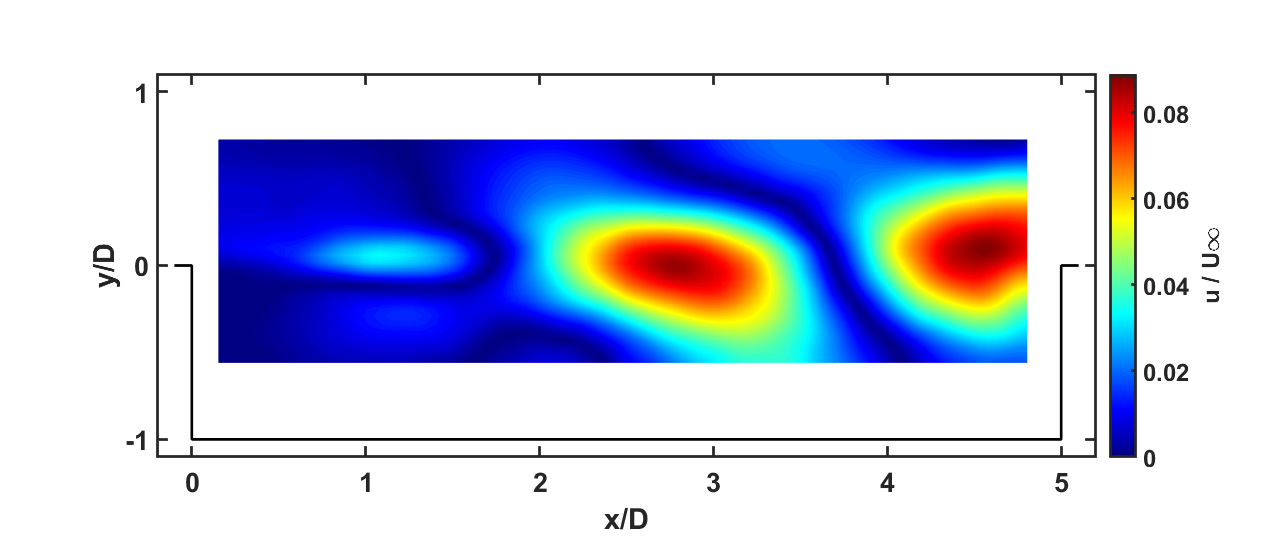

%%Mode2 U
uv_rec = Var2Rms(uv2);
plot_cont_rms(uv_rec,1);

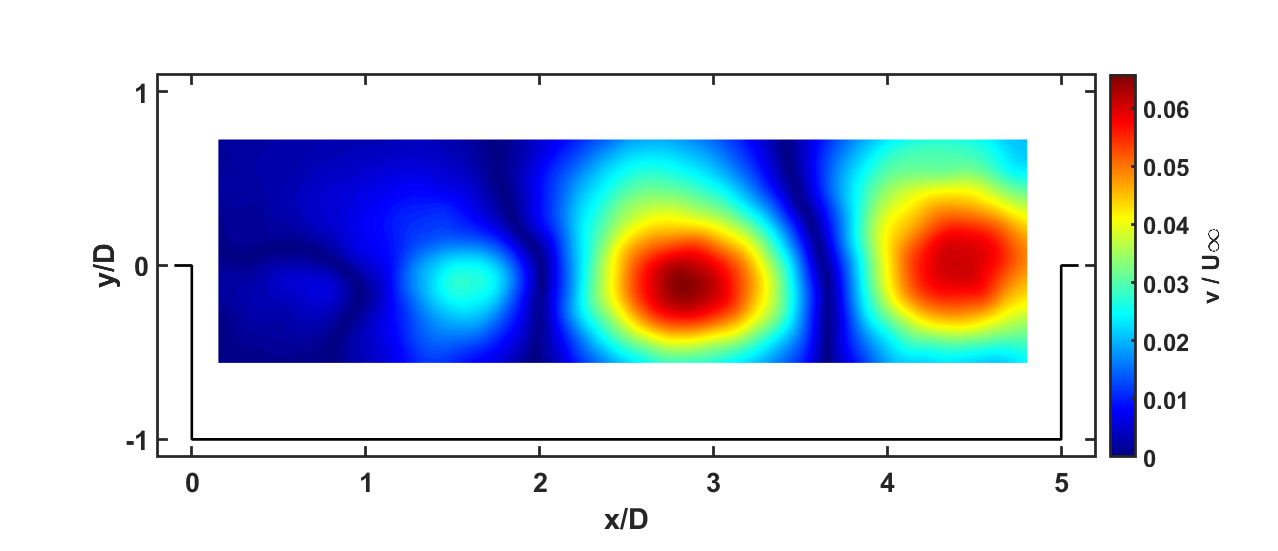

%%Mode2 V
plot_cont_rms(uv_rec,2);

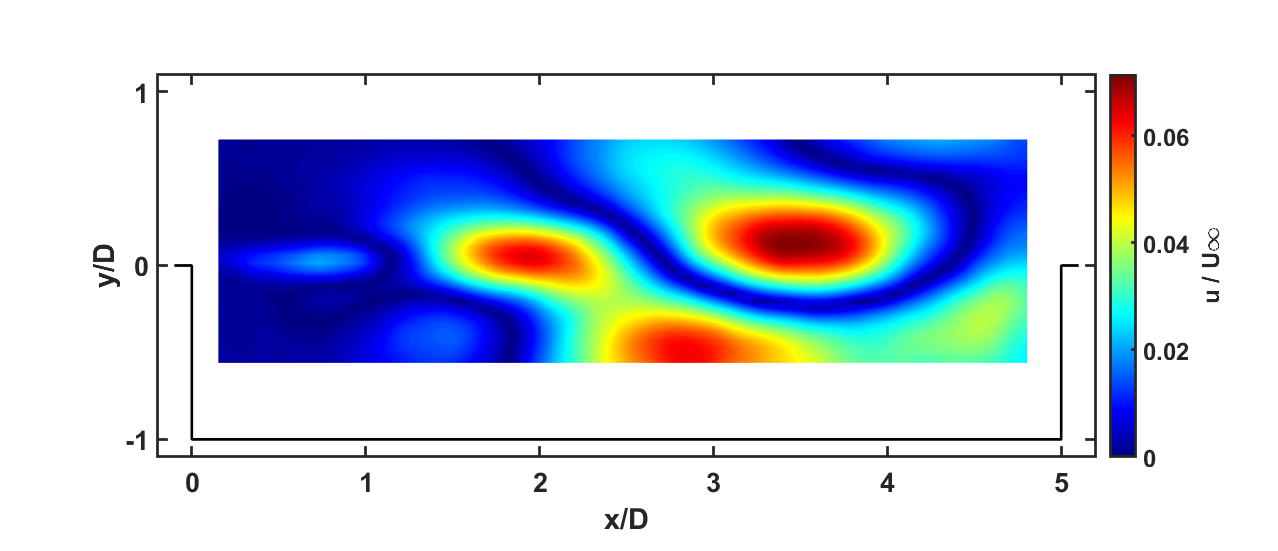

%%Mode3 U
uv_rec = Var2Rms(uv3);
plot_cont_rms(uv_rec,1);

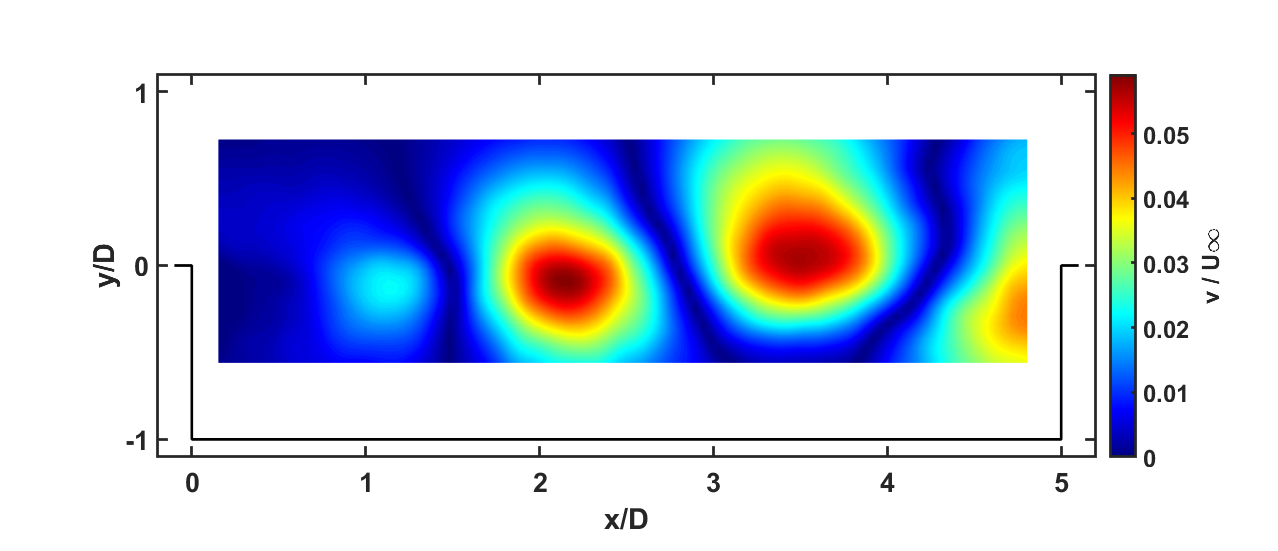

%%Mode3 V
plot_cont_rms(uv_rec,2);

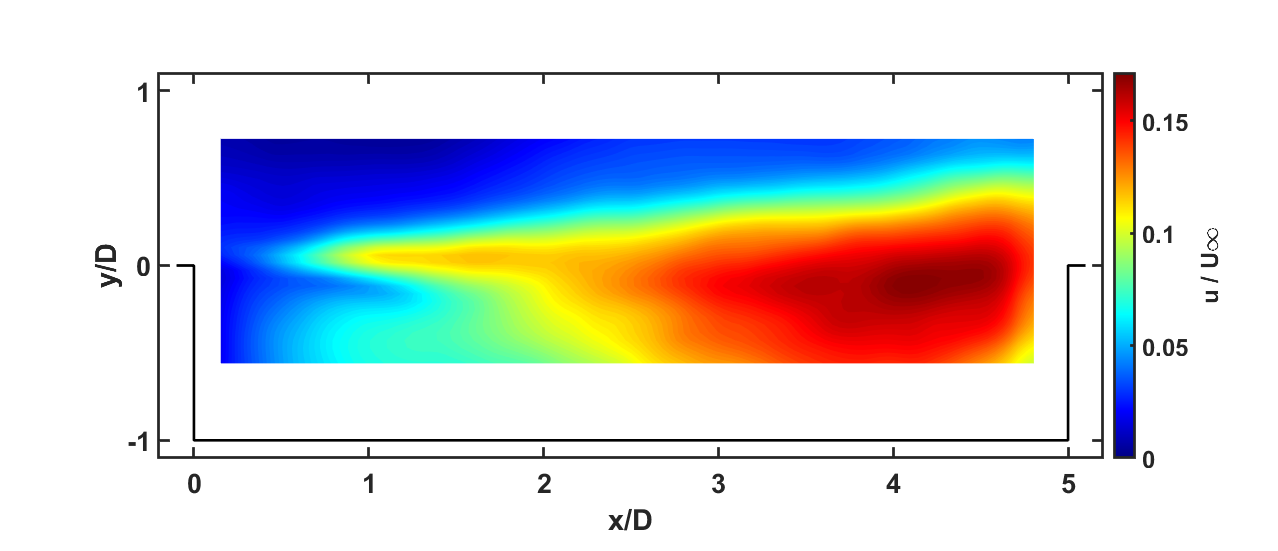

%%Mode3 U
uv_rec = Var2Rms(uv16);
plot_cont_rms(uv_rec,1);

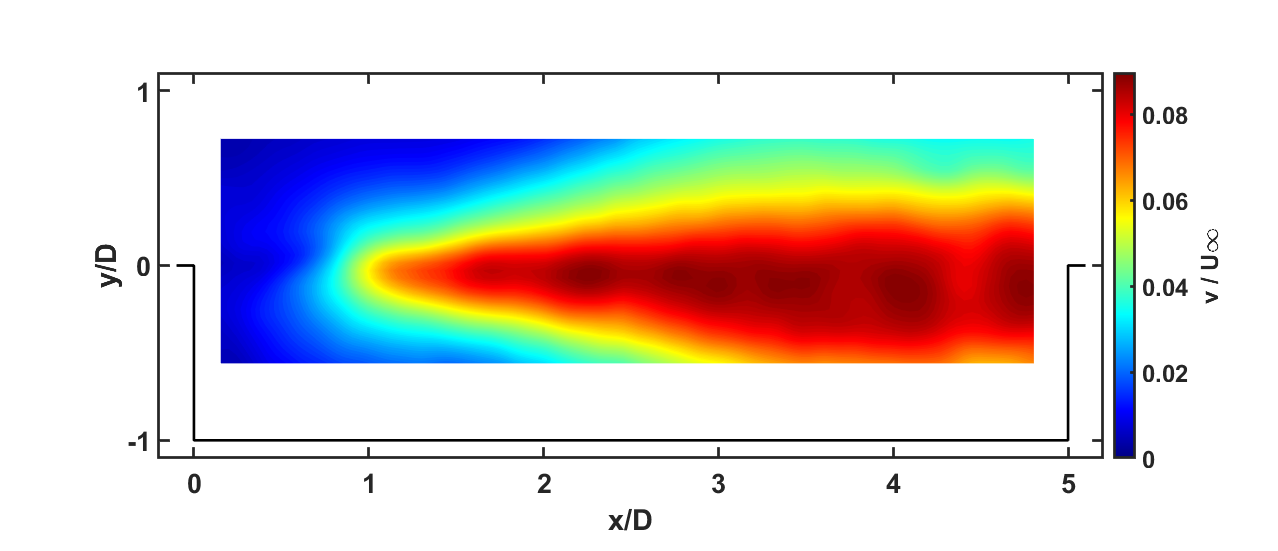

%%Mode3 V
plot_cont_rms(uv_rec,2);

## FigP

clear all;
load('Y:\rawdata\Sandia_cavity\StructuresToPlot_AIAAJournal\FigP.mat');
FigP

FigP = struct with fields:
            lname: 'Rms Frequency POD Modewise'
    completeName1: 'Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\Mode1\uv_rec_var.txt'
    completeName2: 'Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\Mode2\uv_rec_var.txt'
    completeName3: 'Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\Mode3\uv_rec_var.txt'
    completeName4: 'Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\Mode4\uv_rec_var.txt'
    completeName5: 'Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\Mode5\uv_rec_var.txt'
    completeName6: 'Y:\rawdata\Sandia_cavity\SpectralVelocityReconstructions\Mode6\uv_rec_var.txt'


uv1 = load(FigP.completeName1);
uv2 = load(FigP.completeName2);
uv3 = load(FigP.completeName3);
uv4 = load(FigP.completeName4);
uv5 = load(FigP.completeName5);
uv6 = load(FigP.completeName6);

## FigT

clear all;
load('Y:\rawdata\Sandia_cavity\StructuresToPlot_AIAAJournal\FigT.mat');
FigT

FigT = struct with fields:
           lname: 'Gridplot l f'
    completeName: 'Y:\rawdata\Sandia_cavity\SpectralConvergenceResults\eigval_280.txt'


%FigTR11
eig1 = load(FigT.completeName);
eig2 = eig1;
eig2(:,1) = zeros(280,1);
eig2 = eig2/sum(sum(eig2));
eig2 = eig2';

m_index = ones(4,1);
f_index = (6:9)';
eig5 = zeros(193,5);
for ii = 1:size(m_index)
    eig5(f_index(ii,1),m_index(ii,1)) = eig2(f_index(ii,1),m_index(ii,1));
end

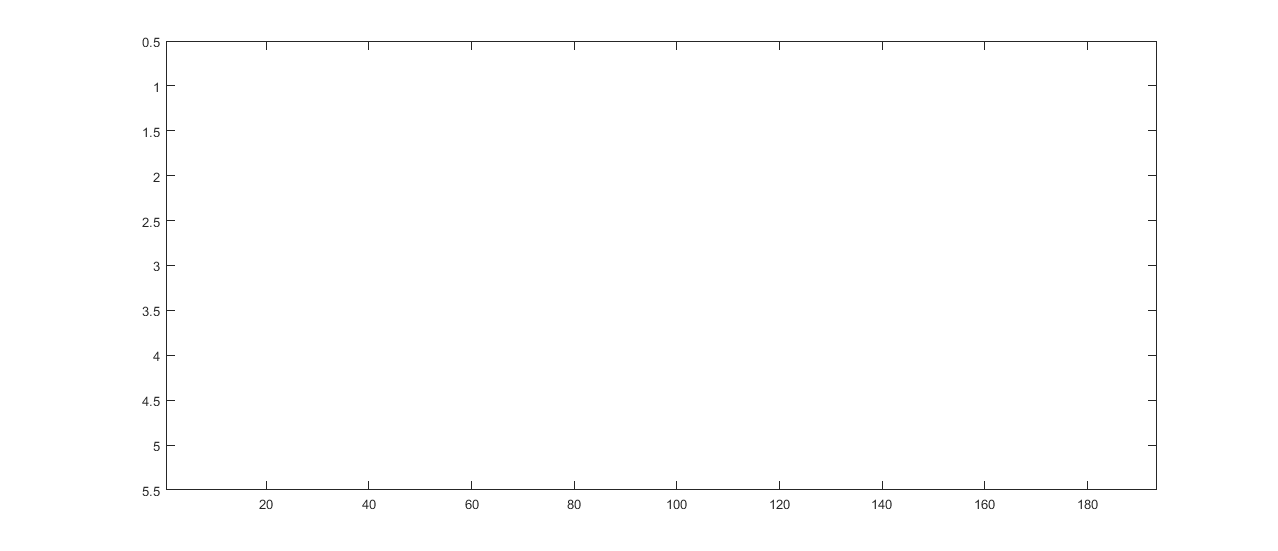

image(flipud(eig5'));
colormap(blackwhite);
caxis([0 max(max(eig5))])